# [Solution] Non-interacting fermions on a tight-binding chain

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr/)

## Solution to Exercise (a): Compute the energy and degeneracy of the many-body ground states

We introduce a new function `nonIntTB` under under the `Util` directory, which computes the ground-state energy and degeneracy as output, taking the hopping amplitudes as input. Please read through the function, which is only six lines long except for the documentation and comments. You can open the file (i) by exploring the "Current Folder" window or (ii) by typing the following command in the "Command Window":

edit nonIntTB.m

If you see an error message that MATLAB cannot find file or directory, please re-run `startup.m`. The shortcut on the upper-right corner (which you created by following `readme.[pdf,mlx]`) is very convenient in this regard!

The function will be used later during the course. To remind yourself of its usage then, you can type the following in the "Command Window":

help nonIntTB

  < Description >
 
  [E_G, d_G, e_1p] = nonIntTB (t)
 
  Compute the energy and degeneracy of the many-body ground state of
  non-interacting spinless fermions on a tight-binding chain. The input
  parameterizes the hopping amplitudes.
  
  t : [numeric vector] Each element t(n) indicates a hopping amplitude from
        site n to site n+1. The length of the vector numel(t) plut 1
        defines the number of chain sites.
 
  < Output >
  E_G : [numeric scalar] Ground-state energy, given by the sum of negative
        elements of the single-particle eigen-energies "e_1p" (see below).
  d_G : [numeric scalar] Ground-state degeneracy, given by 2^(number of
        zero elements of "e_1p"). Here the zero elements are identified up
        to numerical precision noise.
  e_1p : [numeric vector] Eigenvalues of the single-particle Hamiltonian in
        an ascending order.
 
  Written by S.Lee (Sep.02,2022)



The function implements the single-particle Hamiltonian,

$H = \sum_{\ell=1}^{L-1} -t_\ell |\ell+1\rangle\!\langle \ell | - t_\ell^* |\ell\rangle\!\langle\ell+1|$,

as a matrix,

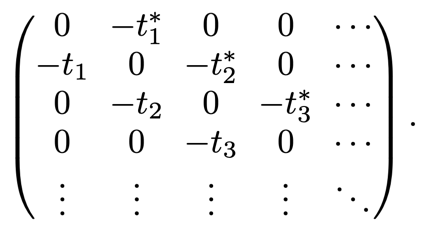

The rows (columns) of the matrix are associated with kets $\{ |\ell\rangle \}$ (bras $\{\langle \ell |\}$). The first diagonal *below* the main diagonal is filled with $\{ -t_\ell \}$ that represent "forward" hoppings, i.e., moving to the sites with larger indices, while the first diagonal *above* the main diagonal is with $\{ -t_\ell^* \}$ for "backward" hoppings.

After diagonalizing the matrix, a tolerance is set so that its eigenvalues (i.e., the single-particle eigen-energies) whose magnitudes are smaller than the tolerance are replaced by zeros. The tolerance is defined in terms of double precision, using `eps`.

With the function, we can easily solve the sub-exercises by only replacing the input to the function.

#### (1) $L = 10$, $t_\ell = 1$ for all $\ell$'s:

[E_G,d_G,e_1p] = nonIntTB (ones(9,1));
fprintf('E_G = %.4g, d_G = %i\n',E_G,d_G);

E_G = -6.027, d_G = 1


We find that the single-particle eigen-energies, `e_1p`, has a symmetry such that all elements have their opposite-sign partners within the array.

e_1p

e_1p =    -1.9190
   -1.6825
   -1.3097
   -0.8308
   -0.2846
    0.2846
    0.8308
    1.3097
    1.6825
    1.9190


e_1p + flip(e_1p,1) % zeros up to numerical precision

ans = 1.0e-14 *

         0
   -0.1332
         0
    0.0444
    0.0500
    0.0500
    0.0444
         0
   -0.1332
         0


Such symmetry is called particle-hole symmetry. Non-interacting tight-binding chains are particle-hole symmetric when there are only nearest-neighbor hoppings, without on-site energies and long-range hoppings. This statement can be simply proven by applying the particle-hole transformation, $\hat{c}_\ell \mapsto (-1)^{\ell+1} \hat{h}_\ell^\dagger$, where $\hat{h}_\ell^\dagger$ creates a "hole" at site $\ell$. Then the Hamiltonian becomes


$$\hat{H} [\{ \hat{h}_\ell, \hat{h}_\ell^\dagger \}] = \sum_{\ell = 1}^{L-1} ( -t_\ell \hat{h}_{\ell+1}^\dagger \hat{h}_{\ell} - t_\ell^* \hat{h}_{\ell}^\dagger \hat{h}_{\ell+1} ),$$


which is basically identical to the original Hamiltonian, except that it's written in $h$'s instead of $c$'s. So the energy eigenvalues of the "hole" Hamiltonian $\hat{H} [\{ \hat{h}_\ell, \hat{h}_\ell^\dagger \}]$ equals to those of the original Hamiltonian, indicating that hole excitations have the same energies as particle excitations. Note that hole excitations Hole excitations mean emptying out the single-particle levels below 0 (that were filled in the ground-state configurations), whle particle excitations filling up the levels above 0 (that were empty in the ground-state configurations).

#### (2) $L = 11$, $t_\ell = 1$ for all $\ell$'s:

[E_G,d_G,e_1p] = nonIntTB (ones(10,1));
fprintf('E_G = %.4g, d_G = %i\n',E_G,d_G);

E_G = -6.596, d_G = 2


Now we have the groud-state degneracy, since there is a zero element in `e_1p`:

e_1p

e_1p =    -1.9319
   -1.7321
   -1.4142
   -1.0000
   -0.5176
         0
    0.5176
    1.0000
    1.4142
    1.7321


#### (3) $L = 11$, $t_\ell = e^{\mathrm{i} \ell}$:

[E_G,d_G,e_1p] = nonIntTB (exp(1i*(1:10).'));
fprintf('E_G = %.4g, d_G = %i\n',E_G,d_G);

E_G = -6.596, d_G = 2


The values of `E_G` and `d_G` equal to those of the above sub-exercise (2). It is because the phase factors in $\{ t_\ell \}$ can be absorbed into the definition of the single-particle bases $\{ | \ell \rangle \}$. Such absorption is possible since hoppings are only between nearest neighbors. In the second quantization language, we consider the transformation $\hat{c}_\ell \mapsto e^{-\mathrm{i} \ell (\ell-1)/2} \hat{c}_\ell$ after which the Hamiltonian becomes the same as one with $t_\ell = 1$ for all $\ell$'s.